# End-to-End Bluetooth BR/EDR PHY Simulation with WLAN Interference and Adaptive Frequency Hopping

This example presents an end-to-end simulation to demonstrate how adaptive frequency hopping (AFH) alters the frequency hopping sequence in Bluetooth® basic rate/enhanced data rate (BR/EDR) physical layer (PHY) and minimizes the impact of WLAN interference using Bluetooth® Toolbox. Unlike basic frequency hopping, AFH excludes the Bluetooth channels that are sources of interference. By excluding these channels from the list of available channels, AFH reassigns the transmission and reception of packets on channels with relatively less interference.

Using this example, you can:

- Generate a Bluetooth BR/EDR waveform.

- Add WLAN interference and additive white Gaussian noise (AWGN) to the generated Bluetooth BR/EDR waveform.

- Transmit and receive Bluetooth BR/EDR waveform by using basic frequency hopping and AFH techniques.

- Decode the received Bluetooth BR/EDR waveform.

- View and compare the packet error rate (PER) and bit error rate (BER) values of the Bluetooth BR/EDR waveforms in the presence of WLAN interference with AFH and basic frequency hopping.

- Visualize the power spectral density of Bluetooth BR/EDR waveforms in the presence of WLAN interference with AFH and basic frequency hopping.

## **Bluetooth BR/EDR PHY**

The Bluetooth standard specifies two PHY modes: BR and EDR. The Bluetooth® Toolbox enables you to model Bluetooth BR/EDR communication system links, as specified in the Bluetooth Core Specification [ 2 ].

The Bluetooth BR mode is mandatory, whereas the EDR mode is optional. The Bluetooth BR/EDR radio implements a 1600 hops/s frequency hopping spread spectrum (FHSS) technique. The radio hops in a pseudo-random way on 79 designated Bluetooth channels. Each Bluetooth channel has a bandwidth of 1 MHz. Each channel is centered at (2402 + k) MHz, where k = 0, 1, ..., 78. The modulation technique on BR and EDR mode payloads is Gaussian frequency shift-keying (GFSK) and differential phase shift-keying (DPSK), respectively. The baud rate is 1 MSymbols/s. The Bluetooth BR/EDR radio uses time division duplex (TDD) in which data transmission occurs in one direction at one time. The transmission alternates in two directions, one after the other. 

For more information about the Bluetooth BR/EDR radio and the protocol stack, see [Bluetooth Protocol Stack](docid:bluetooth_ug#mw_8162673a-b60b-43df-8f02-6da53ee4e146). For more information about Bluetooth BR/EDR packet structures, see [Bluetooth Packet Structure](docid:bluetooth_ug#mw_adbae2d9-4502-4e6f-b5bd-3a650e51e0ec).

## **Adaptive Frequency Hopping**

The objective of using FHSS in Bluetooth is to provide diversity that allows to minimize BER even if the interfering networks or the physical environment renders some channels unusable. Frequency hopping techniques can either implement a fixed sequence of channel hops such as with basic frequency hopping or adapt its hopping sequence dynamically with AFH to varying interference conditions.

Prior to AFH capability, Bluetooth devices implemented the basic frequency hopping scheme. In this approach, a Bluetooth radio hops in a pseudo-random way at the rate of 1600 hops/s. When another wireless device operating in the same 2.4 GHz band comes into the environment, the basic frequency hopping scheme results in occasional collisions. For example, Bluetooth and WLAN are two such networks that operate in the 2.4 GHz frequency band. Bluetooth and WLAN radios often operate in the same physical scenario and on the same device. In these cases, Bluetooth and WLAN transmissions can interfere with each other. This interference impacts the performance and reliability of both networks. This figure shows a scenario in which Bluetooth and WLAN packet transmissions interfere with each other.

 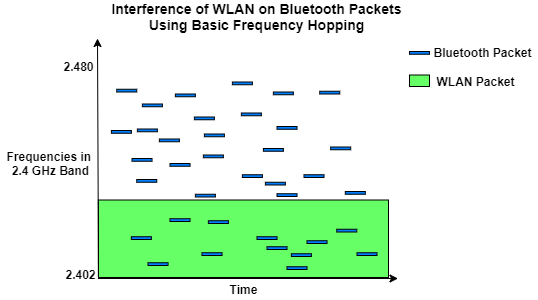

AFH enables Bluetooth to minimize collisions by avoiding sources of interference and excluding them from the list of available channels. This figure shows the previous scenario with AFH enabled.

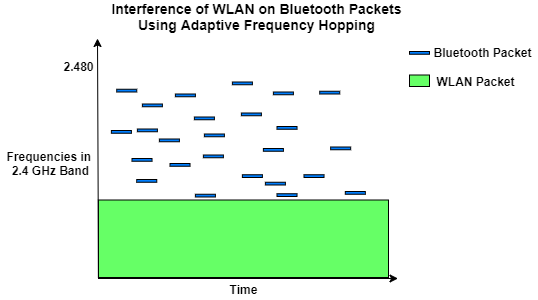

This procedure of remapping involves reducing the number of channels to be used by Bluetooth. The Bluetooth Core Specification [ 2 ] require at least 20 channels for Bluetooth transmissions. For more information about coexistence of Bluetooth and WLAN, see [Bluetooth-WLAN Coexistence](docid:#mw_a30cf33c-6af1-42e8-a6c3-ebcde54ab73c).

## Bluetooth BR/EDR Transmitter and Receiver Chain

This example demonstrates an end-to-end Bluetooth BR/EDR waveform processing by using the frequency hopping mechanism defined in the Bluetooth Core Specification [2]. The generated Bluetooth BR/EDR waveform is frequency modulated and then distorted with WLAN interference. This flowchart shows the Bluetooth transmitter and receiver chain.

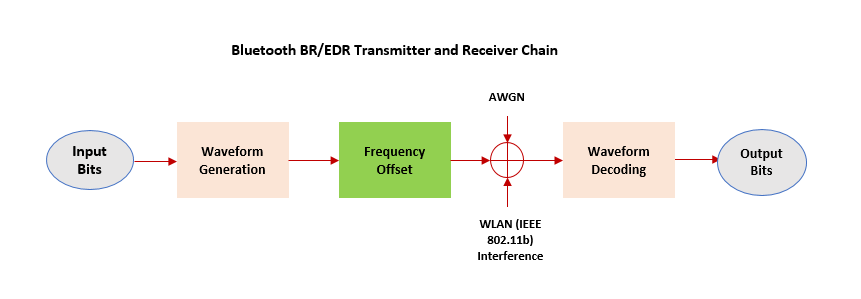

**Transmitter chain**

- Select a channel index for the transmission.

- Generate random input bits.

- Generate a Bluetooth BR/EDR waveform.

- Apply a frequency offset based on the selected channel index.

**Receiver chain**

- Select a channel index for reception.

- Apply a frequency offset based on the selected channel index.

- Decode the Bluetooth BR/EDR waveform to get the output bits.

**Wireless Channel**

- Add WLAN (IEEE 802.11b) interference to Bluetooth BR/EDR waveform.

- Add AWGN to Bluetooth BR/EDR waveform.

**Results**

The example displays these results for basic frequency hopping and AFH.

- The PER and BER for the simulations performed under an additive white gaussian noise (AWGN) channel for a given bit energy to noise density ratio (Eb/No) value

- The received signal spectrum and the spectrogram of the channel

- A plot displaying the selected channel index per transmission or reception slot

## Configure Simulation Parameters

Configure the desired Bluetooth packet type, payload length, PHY mode, and simulation time.

simulationTime = 2*1e6; % Simulation time in microseconds
packetType     = 'DM1'; % Specify baseband packet type
phyMode        = 'BR'; % Specify PHY mode ('BR', 'EDR2M', 'EDR3M')
payloadLength  = 10; % Length of baseband packet in bytes

**Configure Frequency Hopping**

Use the [bluetoothFrequencyHop](docid:bluetooth_ref#obj_bluetoothFrequencyHop) object to select a channel index for the transmission and reception of Bluetooth BR/EDR waveforms.

% Bluetooth frequency hopping
frequencyHop = bluetoothFrequencyHop;
frequencyHop.SequenceType = 'Connection Adaptive';

**Configure Bluetooth PHY**

Use the `helperBluetoothPHY` helper object to model the Bluetooth BR/EDR waveform transmission and reception.

% Configure Bluetooth PHY transmission
phyTx = helperBluetoothPHY;
phyTx.Mode = phyMode;

% Configure Bluetooth PHY reception
phyRx = helperBluetoothPHY;
phyRx.Mode = phyMode;

**Configure Channel and WLAN Interference:**

Use `helperBluetoothChannel` object to configure the wireless channel. You can set the `EbNo` value for the AWGN channel. To generate the interfering WLAN waveform, use the `helperBluetoothGenerateWLANWaveform` function. Specify the sources of WLAN interference by using `wlanInterferenceSource` parameter. The WLAN signal is present between -10 to 10 MHz throughout the simulation. Use one of these options to specify the source of WLAN interference.

- ‘Generated’: To add WLAN signal from the WLAN Toolbox™, select this option.

- ‘BasebandFile’: To add a WLAN signal from a baseband file (`.bb`), select this option and specify the baseband file name in the `WLANBBFilename` property. If you do not specify the `.bb` file, the example uses the default `.bb` file, `WLANNonHTDSSS.bb`, to add the WLAN signal.

- ‘None’: No WLAN signal is added.

AWGN is present throughout the simulation.

% Specify as one of 'Generated' | 'BasebandFile' | 'None'
wlanInterferenceSource = 'BasebandFile';
wlanBBFilename = 'WLANNonHTDSSS.bb'; % Default baseband file

% Configure wireless channel
channel = helperBluetoothChannel;
channel.EbNo = 22; % Ratio of energy per bit (Eb) to the spectral noise density (No) in dB
channel.SIR = -20; % Signal to interference ratio in dB
if ~strcmpi(wlanInterferenceSource, 'None')
    % Generate the WLAN waveform
    wlanWaveform = helperBluetoothGenerateWLANWaveform(wlanInterferenceSource, wlanBBFilename);
    
    % Add the WLAN interference to Bluetooth channel
    addWLANWaveform(channel, wlanWaveform);
end

**Simulation Setup**

Initialize parameters to perform the end-to-end Bluetooth BR/EDR simulation.

slotTime = 625; % Bluetooth slot duration in microseconds

% Simulation time in terms of slots
numSlots = floor(simulationTime/slotTime);

% Slot duration, including transmission and reception
slotValue = phyTx.slotsRequired(packetType)*2;

% Number of Central transmission slots
numCentralTxSlots = floor(numSlots/slotValue);

% Total number of Bluetooth physical channels
numBluetoothChannels = 79;

% errorsBasic and errorsAdaptive store relevant bit and packet error
% information per channel. Each row stores the channel index, bit errors,
% packet errors, total bits, and BER per channel. errorsBasic and
% errorsAdaptive arrays store these values for basic frequency hopping
% and AFH, respectively.
[errorsBasic, errorsAdaptive] = deal(zeros(numBluetoothChannels,5));

% Initialize first column with channel numbers
[errorsBasic(:,1), errorsAdaptive(:,1)] = deal(0:78);

% Initialize variables for calculating PER and BER
[berBasic, berAdaptive, bitErrors] = deal(0);
badChannels = zeros(1,0);
totalTransmittedPackets = numCentralTxSlots;

% Number of bits per octet
octetLength = 8;

% Sample rate and input clock used in PHY processing
samplePerSymbol = 88;
symbolRate = 1e6;
sampleRate = symbolRate*samplePerSymbol;
inputClock = 0;

% Store hop index
hopIndex = zeros(1, numCentralTxSlots);

% Index to hop index vector
hopIdx = 1;

% Baseband packet structure
basebandData = struct(...
    'LTAddr',1,             ... % Logical transport address
    'PacketType',packetType,... % Packet type
    'Payload',zeros(1,phyTx.MaxPayloadSize), ... % Payload
    'PayloadLength',0,  ... % Payload length
    'LLID',[0; 0],      ... % Logical link identifier
    'SEQN',0,           ... % Sequence number
    'ARQN',1,           ... % Acknowledgment flag
    'IsValid',false);   ... % Flag to identify the status of cyclic redundancy check (CRC) and header error control (HEC)

% Bluetooth signal structure
bluetoothSignal = struct(...
    'PacketType',packetType, ... % Packet type
    'Waveform',[],           ... % Waveform
    'NumSamples',[],         ... % Number of samples
    'SampleRate',sampleRate, ... % Sample rate
    'SamplesPerSymbol',samplePerSymbol,      ... % Samples per symbol in Hz
    'Payload',zeros(1,phyTx.MaxPayloadSize), ... % Payload
    'PayloadLength',0, ... % Payload length in bytes
    'SourceID',0,      ... % Source identifier
    'Bandwidth',1,     ... % Bandwidth
    'NodePosition',[0 0 0], ... % Node position
    'CenterFrequency',centerFrequency(phyTx), ... % Center frequency
    'StartTime',0, ... % Waveform start time in microseconds
    'EndTime',0,   ... % Waveform end time in microseconds
    'Duration',0); ... % Waveform duration in microseconds

% Set the elapsed time to process each packet during PHY transmission and
% reception time slots.
elapsedTxRxTime = slotValue*2;

To visualize the Bluetooth BR/EDR waveforms, create a [spectrumAnalyzer](docid:dsp_ref#mw_d312d509-f3fe-49bd-9fe1-dd35c86ae976) object.

% Spectrum analyzer for basic frequency hopping
spectrumAnalyzerBasic = spectrumAnalyzer(...
    'Name','Bluetooth Basic Frequency Hopping', ...
    'ViewType','Spectrum and spectrogram', ...
    'TimeResolutionSource','Property', ...
    'TimeResolution',0.0005, ...    % In seconds
    'SampleRate',sampleRate, ...    % In Hz
    'TimeSpanSource','Property', ...
    'TimeSpan', 0.05, ...           % In seconds
    'RBWSource', 'property', ...
    'RBW', 257.812e3, ...
    'AxesLayout', 'Horizontal', ...
    'FrequencyOffset',2441*1e6, ... % In Hz
    'ColorLimits',[-20 15]);

% Spectrum analyzer for AFH
spectrumAnalyzerAdaptive = spectrumAnalyzer(...
    'Name','Bluetooth Adaptive Frequency Hopping', ...
    'ViewType','Spectrum and spectrogram', ...
    'TimeResolutionSource','Property', ...
    'TimeResolution',0.0005, ...    % In seconds
    'SampleRate',sampleRate, ...    % In Hz
    'TimeSpanSource','Property', ...
    'TimeSpan',0.05, ...            % In seconds
    'RBWSource', 'property', ...
    'RBW', 257.812e3, ...
    'AxesLayout','Horizontal', ...
    'FrequencyOffset',2441*1e6, ... % In Hz
    'ColorLimits',[-20 15]);

## **Simulations**

The Bluetooth transmitter and receiver chain is simulated using basic frequency hopping and AFH. Using per channel PER and BER results of basic frequency hopping, derive a list of used channels. The list of used channels is fed as an input to the simulation using AFH.

**Basic Frequency Hopping**

The simulation runs for all the specified number of Central transmission slots. Simulates the transmitter chain, receiver chain, and channel for each slot. At the end of the simulation, the example computes the PER and BER for all the Bluetooth BR/EDR waveforms.

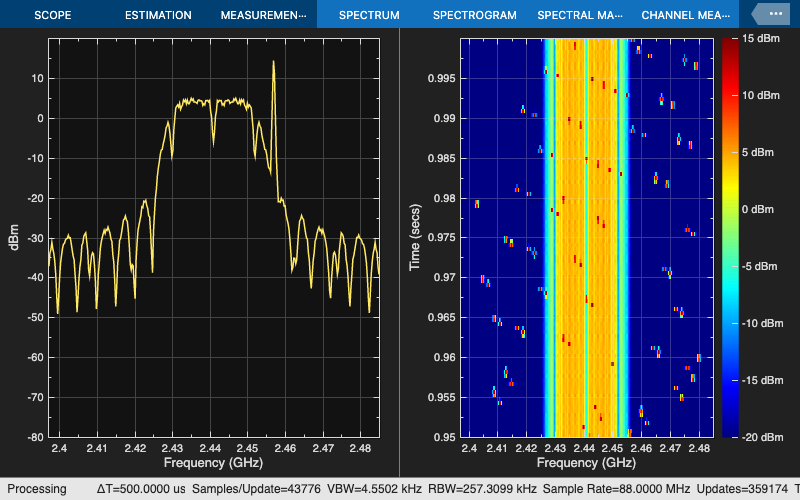

% Set the default random number generator ('twister' type with seed value 0).
% The seed value controls the pattern of random number generation. For high
% fidelity simulation results, change the seed value and average the
% results over multiple simulations.
sprev = rng('default');
for slotIdx = 0:slotValue:numSlots-slotValue
    % Update clock
    inputClock = inputClock + elapsedTxRxTime;

    % Frequency hopping
    [channelIndex,~] = nextHop(frequencyHop,inputClock);
    
    % PHY transmission
    stateTx = 1; % Transmission state
    TxBits = randi([0 1],payloadLength*octetLength,1);
    basebandData.Payload = TxBits;
    basebandData.PayloadLength = payloadLength;
    
    % Generate whiten initialization vector from clock
    clockBinary = int2bit(inputClock,28,false)';
    whitenInitialization = [clockBinary(2:7)'; 1];
    
    % Update the PHY with request from the baseband layer
    updatePHY(phyTx,stateTx,channelIndex,whitenInitialization,basebandData);
    
    % Initialize and pass elapsed time as zero
    elapsedTime = 0;
    [nextTxTime,btWaveform] = run(phyTx,elapsedTime); % Run PHY transmission
    run(phyTx, nextTxTime); % Update next invoked time

    % Channel
    bluetoothSignal.Waveform = btWaveform;
    bluetoothSignal.NumSamples = numel(btWaveform);
    bluetoothSignal.CenterFrequency = centerFrequency(phyTx);
    channel.ChannelIndex = channelIndex;
    bluetoothSignal = run(channel,bluetoothSignal,phyMode);
    distortedWaveform = bluetoothSignal.Waveform;

    % PHY reception
    stateRx = 2; % Reception state
    
    % Update the PHY with request from the baseband layer
    updatePHY(phyRx,stateRx,channelIndex,whitenInitialization);
    [nextRxTime,~] = run(phyRx,elapsedTime,bluetoothSignal);
    bluetoothSignal.NumSamples = 0;
    run(phyRx,nextRxTime,bluetoothSignal); % Run PHY reception
    chIdx = channelIndex + 1;

    % Calculate error rate upon successful decoding the packet
    if phyRx.Decoded
        rxBitsLength = phyRx.DecodedBasebandData.PayloadLength*octetLength;
        RxBits = phyRx.DecodedBasebandData.Payload(1:rxBitsLength);
        
        % BER calculation
        txSymLength = length(TxBits);
        rxSymLength = length(RxBits);
        minSymLength = min(txSymLength,rxSymLength);
        if minSymLength > 0
            bitErrors = sum(xor(TxBits(1:minSymLength),RxBits(1:minSymLength)));
            totalBits = minSymLength;
            
            % Bit errors found in channel
            errorsBasic(chIdx,2) = errorsBasic(chIdx,2) + bitErrors;
            
            % Total bits transmitted in channel
            errorsBasic(chIdx,4) = errorsBasic(chIdx,4) + totalBits;
        end
        if ~phyRx.DecodedBasebandData.IsValid || bitErrors
            % Packet errors found in channel
            errorsBasic(chIdx,3) = errorsBasic(chIdx,3) + 1;
        end
    else
        % Packet errors found in channel
        errorsBasic(chIdx,3) = errorsBasic(chIdx,3) + 1;
    end
    hopIndex(hopIdx) = channelIndex;
    hopIdx = hopIdx + 1;

    % Plot spectrum
    spectrumAnalyzerBasic(btWaveform + wlanWaveform(1:numel(btWaveform)));
    pause(0.01);
end

In the previous figure, the plot on the left shows the spectrum of the Bluetooth BR/EDR waveform distorted with WLAN interference in the frequency domain and passed through the AWGN channel. The plot on the right shows that the WLAN signal is present from –10 to 10 MHz. The results show that Bluetooth packets with the interfering WLAN signal overlap.

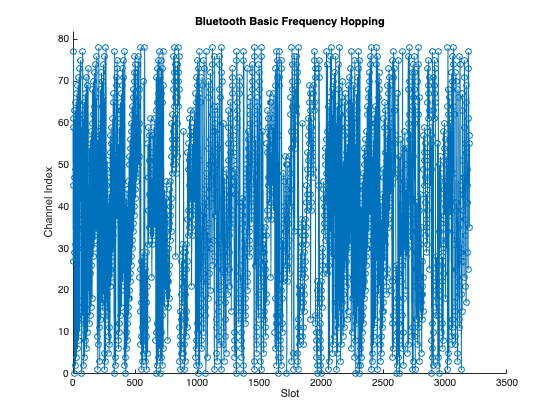

% Plot selected channel index per slot
figBasic = figure('Name','Basic frequency hopping');
axisBasic = axes(figBasic);
xlabel(axisBasic,'Slot');
ylabel(axisBasic,'Channel Index');
ylim(axisBasic,[0 numBluetoothChannels+3]);
title(axisBasic,'Bluetooth Basic Frequency Hopping');
hold on;
plot(axisBasic,0:slotValue:numSlots-slotValue,hopIndex,'-o');

The preceding plot displays the selected channel index per transmission or reception slot using basic frequency hopping. In this case all of the channels are used channels.

**Channel Classification**

The channels with more packet errors are marked as bad channels. Based on the bit and packet errors collected from the above simulation, calculate the PER and BER.

% Select 25 channels with highest packet errors as bad channels
[~,indexes] = sort(errorsBasic(:,3),'descend');
badChannelIdx = min(nnz(errorsBasic(:,3)),25);
if badChannelIdx ~= 0
    badChannels = indexes(1:badChannelIdx) - 1;
end
usedChannels = setdiff(0:numBluetoothChannels-1,badChannels);

% BER per channel calculation
errorsBasic(:,5) = errorsBasic(:,2)./errorsBasic(:,4);
errorsBasic(:,5) = fillmissing(errorsBasic(:,5),'constant',0);
ber = nonzeros(errorsBasic(:,5));
if ~isempty(ber)
    berBasic = mean(ber);
end

% PER calculation
packetErrorsBasic = sum(errorsBasic(:,3));
perBasic = packetErrorsBasic/totalTransmittedPackets;

% Reset
hopIdx = 1;
[inputClock,bitErrors] = deal(0);
fprintf('PER of Bluetooth BR/EDR waveforms using basic frequency hopping: %.4f\n',perBasic);

PER of Bluetooth BR/EDR waveforms using basic frequency hopping: 0.3337


fprintf('BER of Bluetooth BR/EDR waveforms using basic frequency hopping: %.4f\n',berBasic);

BER of Bluetooth BR/EDR waveforms using basic frequency hopping: 0.0556


**Adaptive Frequency Hopping**

Set the value of the sequence type as `'Connection adaptive'` and specify the classified used channels.

frequencyHop.SequenceType = 'Connection adaptive';
frequencyHop.UsedChannels = usedChannels;

Run the simulation using AFH and compute the PER and BER.

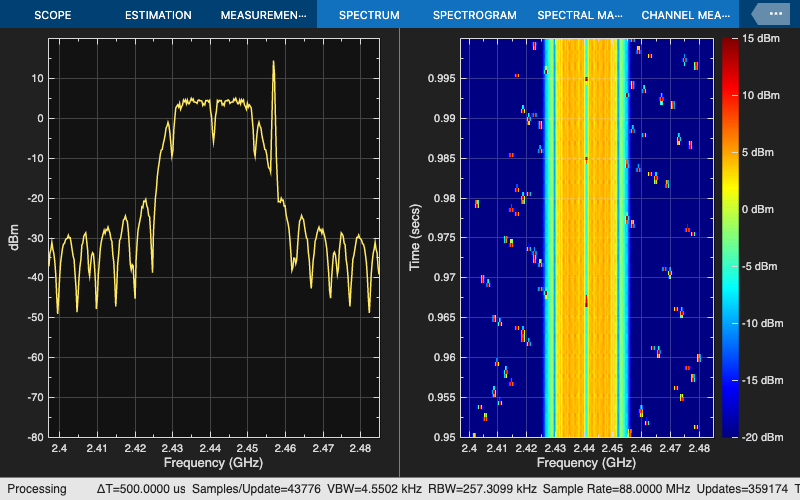

% Set the default random number generator ('twister' type with seed value 0).
% The seed value controls the pattern of random number generation. For high
% fidelity simulation results, change the seed value and average the
% results over multiple simulations.
rng('default');
for slotIdx = 0:slotValue:numSlots-slotValue
    % Update clock
    inputClock = inputClock + elapsedTxRxTime;

    % Frequency hopping
    [channelIndex,~] = nextHop(frequencyHop,inputClock);

    % PHY transmission
    stateTx = 1; % Transmission state
    TxBits = randi([0 1],payloadLength*octetLength,1);
    basebandData.Payload = TxBits;
    basebandData.PayloadLength = payloadLength;
    
    % Generate whiten initialization vector from clock
    clockBinary = int2bit(inputClock,28,false)';
    whitenInitialization = [clockBinary(2:7)'; 1];
    
    % Update the PHY with request from the baseband layer
    updatePHY(phyTx,stateTx,channelIndex,whitenInitialization,basebandData);
    
    % Initialize and pass elapsed time as zero
    elapsedTime = 0;
    [nextTxTime,btWaveform] = run(phyTx,elapsedTime); % Run PHY transmission
    run(phyTx,nextTxTime); % Update next invoked time

    % Channel
    bluetoothSignal.Waveform = btWaveform;
    bluetoothSignal.NumSamples = numel(btWaveform);
    bluetoothSignal.CenterFrequency = centerFrequency(phyTx);
    channel.ChannelIndex = channelIndex;
    bluetoothSignal = run(channel,bluetoothSignal,phyMode);
    distortedWaveform = bluetoothSignal.Waveform;

    % PHY reception
    stateRx = 2; % Reception state
    
    % Update the PHY with request from the baseband layer
    updatePHY(phyRx,stateRx,channelIndex,whitenInitialization);
    [nextRxTime,~] = run(phyRx,elapsedTime,bluetoothSignal);
    bluetoothSignal.NumSamples = 0;
    run(phyRx,nextRxTime,bluetoothSignal); % Run PHY reception
    chIdx = channelIndex + 1;
    
    % Calculate error rate upon successful decoding the packet
    if phyRx.Decoded
        rxBitsLength = phyRx.DecodedBasebandData.PayloadLength*octetLength;
        RxBits = phyRx.DecodedBasebandData.Payload(1:rxBitsLength);
        
        % BER calculation
        txSymLength = length(TxBits);
        rxSymLength = length(RxBits);
        minSymLength = min(txSymLength,rxSymLength);
        if minSymLength > 0
            bitErrors = sum(xor(TxBits(1:minSymLength),RxBits(1:minSymLength)));
            totalBits = minSymLength;
            
            % Bit errors found in channel
            errorsAdaptive(chIdx,2) = errorsAdaptive(chIdx,2) + bitErrors;
            
            % Total bits transmitted in channel
            errorsAdaptive(chIdx,4) = errorsAdaptive(chIdx,4) + totalBits;
        end

        if ~phyRx.DecodedBasebandData.IsValid || bitErrors
            % Packet errors found in channel
            errorsAdaptive(chIdx, 3) = errorsAdaptive(chIdx, 3) + 1;
        end
    else
        % Packet errors found in channel
        errorsAdaptive(chIdx, 3) = errorsAdaptive(chIdx, 3) + 1;
    end
    hopIndex(hopIdx) = channelIndex;
    hopIdx = hopIdx + 1;

    % Plot spectrum
    spectrumAnalyzerAdaptive(btWaveform + wlanWaveform(1:numel(btWaveform)));
    pause(0.01);
end

In the previous plot, you can observe that the transmission of Bluetooth packets does not overlap with the WLAN signal.  AFH excludes the channels that are sources of WLAN interference and reassigns the transmission of Bluetooth packets on channels with relatively less interference.

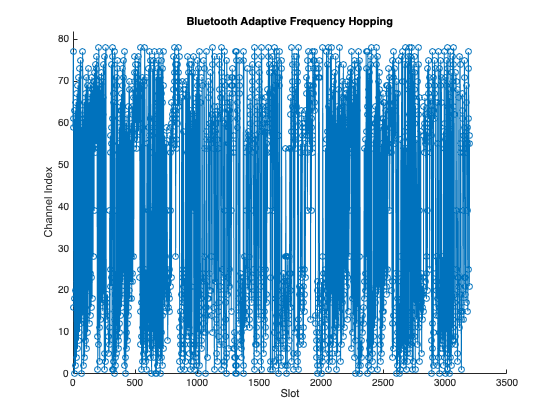

% Plot selected channel index per slot
figAdaptive = figure('Name','Adaptive Frequency Hopping');
axisAdaptive = axes(figAdaptive);
xlabel(axisAdaptive,'Slot');
ylabel(axisAdaptive,'Channel Index');
title(axisAdaptive,'Bluetooth Adaptive Frequency Hopping');
ylim(axisAdaptive,[0 numBluetoothChannels+3]);
hold on;
plot(axisAdaptive,0:slotValue:numSlots-slotValue,hopIndex,'-o');

The preceding plot displays the selected channel index per transmission or reception slot using AFH. To minimize the packet and bit errors in the wireless channel, AFH selects only used channels for transmission or reception of Bluetooth BR/EDR waveforms

Compute the PER and BER of the Bluetooth BR/EDR waveforms with AFH.

% BER per channel calculation
errorsAdaptive(:,5) = errorsAdaptive(:,2)./errorsAdaptive(:,4);
errorsAdaptive(:,5) = fillmissing(errorsAdaptive(:,5),'constant',0);
ber = nonzeros(errorsAdaptive(:,5));
if ~isempty(ber)
    berAdaptive = mean(ber);
end

% PER calculation
packetErrorsAdaptive = sum(errorsAdaptive(:,3));
perAdaptive = packetErrorsAdaptive/totalTransmittedPackets;
fprintf('PER of Bluetooth BR/EDR waveforms using adaptive frequency hopping: %.4f\n',perAdaptive);

PER of Bluetooth BR/EDR waveforms using adaptive frequency hopping: 0.0625


fprintf('BER of Bluetooth BR/EDR waveforms using adaptive frequency hopping: %.4f\n',berAdaptive);

BER of Bluetooth BR/EDR waveforms using adaptive frequency hopping: 0.0022


% Restore previous setting of random number generation
rng(sprev);

The PER and BER values of the Bluetooth BR/EDR waveforms are less with AFH as compared with basic frequency hopping.

This example simulates an end-to-end transmitter-receiver chain to study how AFH mitigates interference between the Bluetooth BR/EDR and WLAN signals. The simulation results verify that the PER and the BER of the Bluetooth BR/EDR waveforms with WLAN interference is less with AFH as compared to basic frequency hopping.

## Appendix

The example uses these helpers:

- [`helperBluetoothPHY` ](matlab:openExample("bluetooth/BluetoothFrequencyHoppingExample","supportingFile","helperBluetoothPHY"))— Configure and simulate Bluetooth PHY

- [`helperBluetoothChannel`](matlab:openExample("bluetooth/BluetoothFrequencyHoppingExample","supportingFile","helperBluetoothChannel")) — Configure and simulate wireless channel

- [`helperBluetoothGenerateWLANWaveform`](matlab:openExample("bluetooth/BluetoothFrequencyHoppingExample","supportingFile","helperBluetoothGenerateWLANWaveform")) — Generate WLAN waveform to be added as an interference to Bluetooth waveforms

## Selected Bibliography

- Bluetooth® Technology Website. "Bluetooth Technology Website | The Official Website of Bluetooth Technology." Accessed November 29, 2021. [https://www.bluetooth.com/.](https://www.bluetooth.com)

- Bluetooth Special Interest Group (SIG). "Bluetooth Core Specification" Version 5.3, Accessed November 29, 2021. [https://www.bluetooth.com/specifications/specs/.](https://www.bluetooth.com/specifications/specs/)

*Copyright 2020-2022 The MathWorks, Inc.*